# Gierer-Meihhardt equations

PS5_GM_equation.mlx

Joe Howard, modified from Hugo Bowne-Anderson 2014

April 8, 2024

In this script, we solve the Gierer-Meinhardt equations 12a/b or 15a/b from (Kybernetik, 12:30-39, 1972) for a variety of parameters.

    The partial differential equations are the dimensionless G-M system:


$$\frac{\partial }{\partial t}a\left(x,t\right)=\frac{a^2 }{h+h_0 }-a+\sigma +D\frac{\partial^2 }{\partial x^2 }a$$



$$\frac{\partial }{\partial t}h\left(x,t\right)=\omega \left(a^2 -h\right)+\frac{\partial^2 }{\partial x^2 }h$$


%Notes:

(1) the derivates are partial derivatives (t is time, x is space);

(2) *t*, *x*, *a* and *h* are all dimensionless;

(4) $D$ is ratio of diffusion constants: activator/inhibitor and is < 1

(5) $\omega$ is a reaction term

(6) $\sigma$ is a baseline synthesis term for a (assumed small, 0.01).

7) $h_0$ is a small positive term (0.1); it keeps the first term in Eqn 1 finite

clear;
close all;

GM_solve_record is the PDE solver. It takes 3 main parameters:

P(1) = $D$

P(2) = $\omega$

P(3) = $\sigma$ (chosen to be close to zero);

There are also three other constants specified below:

tmax = amount of time that we run the system;

delt = time increment;

L = length (spatial) of the system;

and there is h0, which is set at 0.1 in the function

GM_solve_record outputs the concentrations of activator and inhibitor over the time course and plots the solution as surfaces for $a\left(x,t\right)$ and $h\left(x,t\right)$ and as an animation.

We consider the phase plane of the G-M system with x-axis given by D (ratio of diffusion constants: activator/inhibitor) and y-axis $\omega$ (the reaction

% term) while keeping everything else constant.

### Question 1.

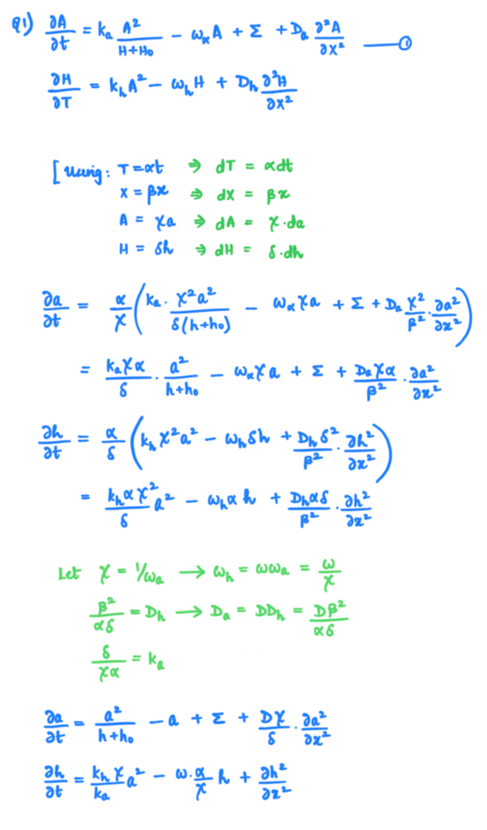

### Question 2.

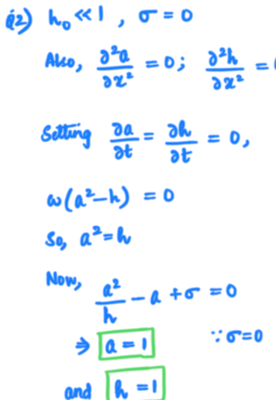

### Question 3.

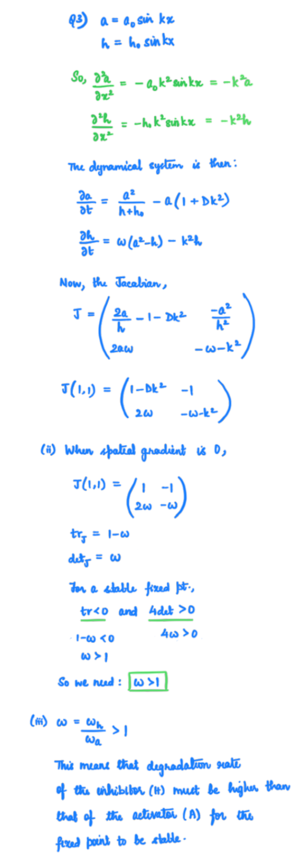

### Question 4.

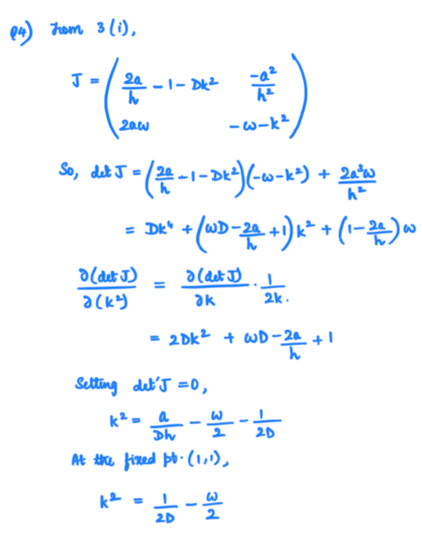

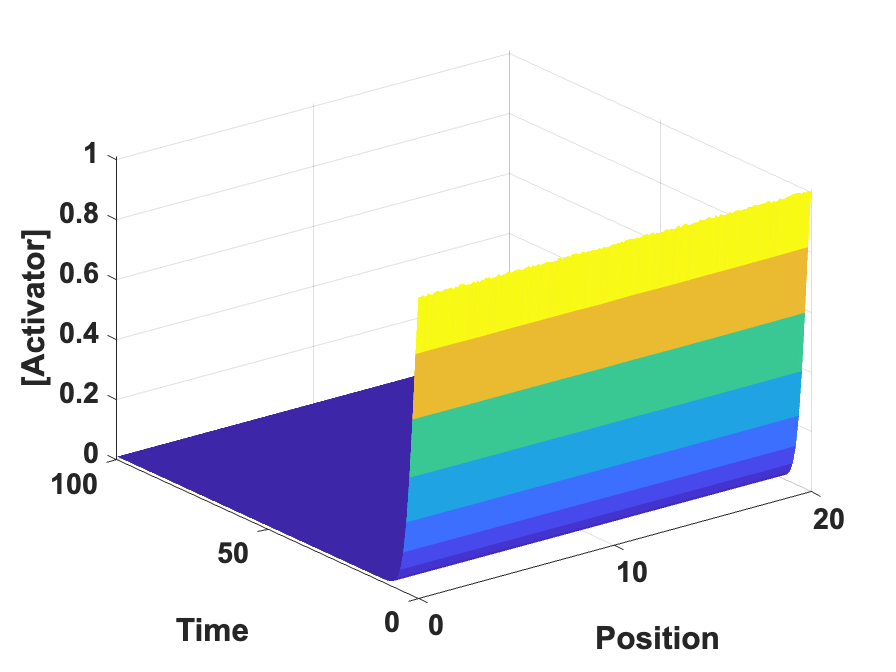

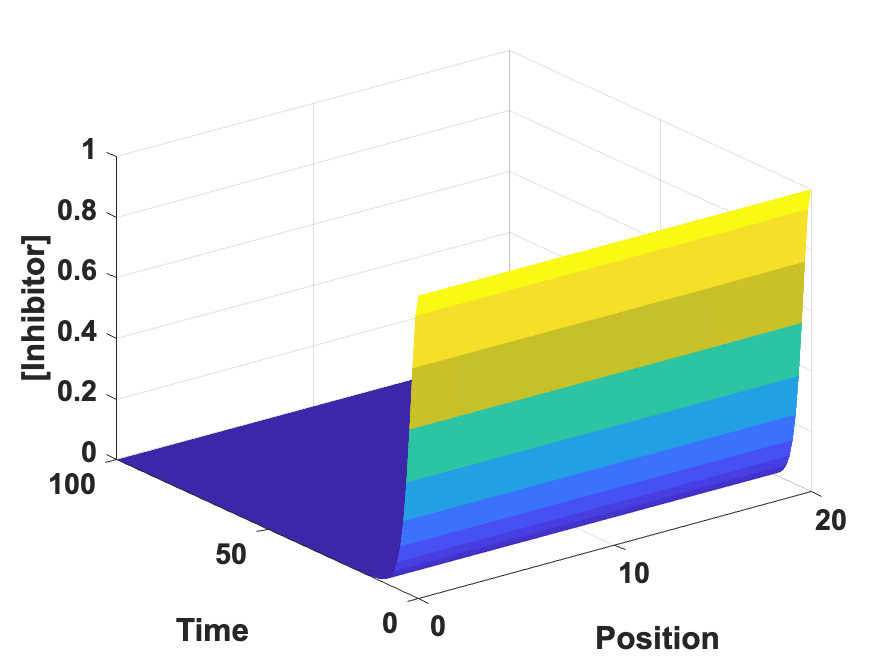

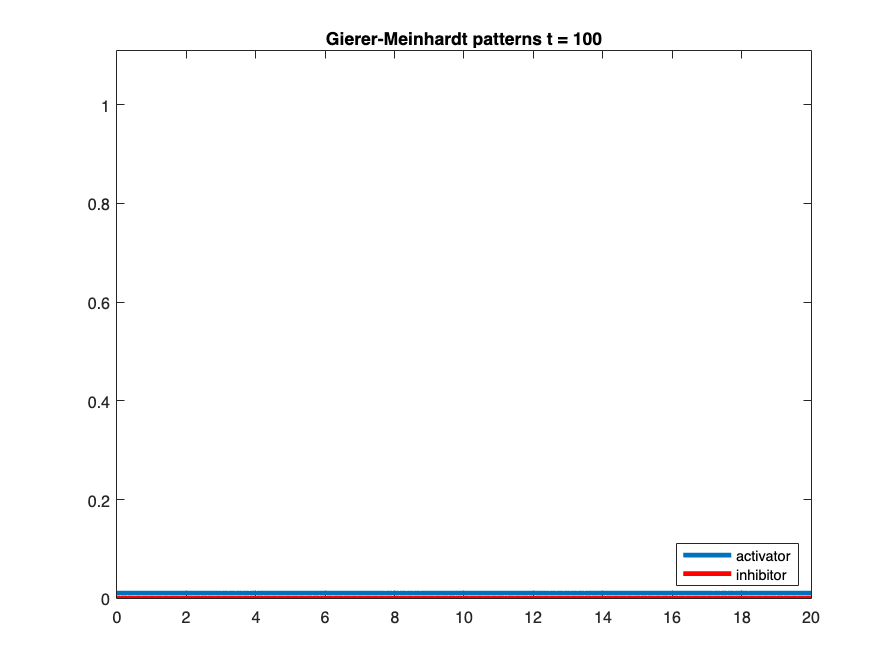

tmax = 100;     %maximum time (can be changed from 50 to 500 if necessary)
delt = 1;      %time interval
L = 20;        %length
% P = [0.05 ; 2 ; 0.01 ];     %Spatial pattern
% P = [0.4 ; 2 ; 0.01 ];      %Homogenous in time and space
% P = [0.4 ; 1; 0.01];       %temporal oscillation
P = [0.4 ; 0.5; 0.01];     %trivial solution
soln = GM_solve_record_JH(P , tmax , delt, L, 'test_pattern1.avi');

(i) The wavelength from the plot is ~3.25 units. Based on the prediction from question 4, it is ~2.09 units.

(ii) The steady fixed point occurs at (a, h) = (0.75, 0.575). The prediction from question 2 was (1, 1).

(iii) 

(iv) The fixed point occurs at (0, 0). The Jacobian evaluated at (0, 0) shows that the fixed point is stable (see below).

    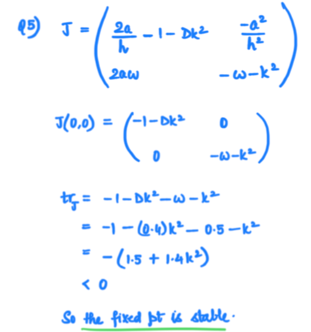

## Phase diagram

Alter P(1) = D and P(2) = $\omega$ to move around the phase plane & draw (by hand or by comouter) a phase diagram for this Gierer-Meinhardt system with D on the x-axis and $\omega$ on the y-axis.

    0.0500
    0.0500
    0.0100



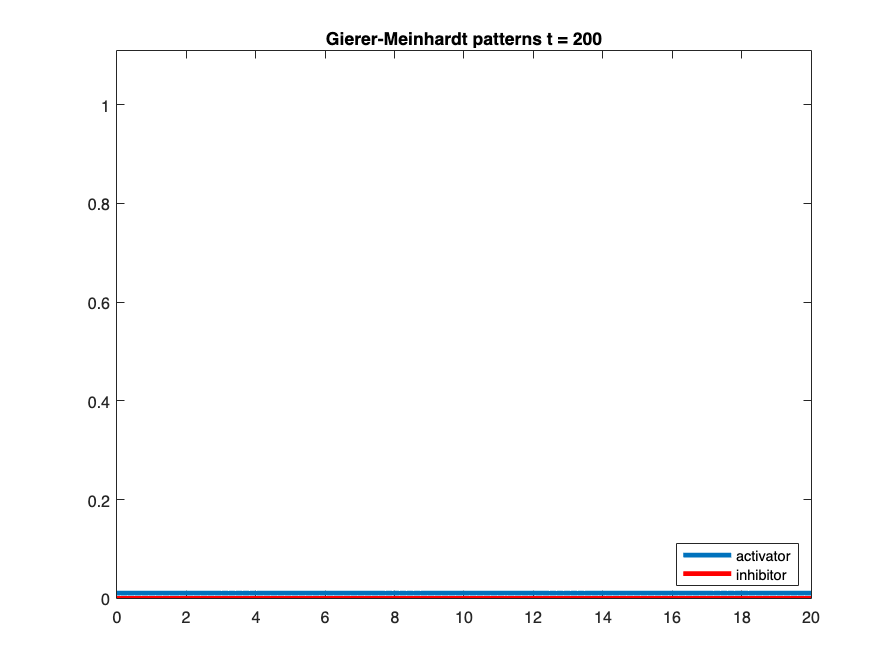

    0.0500
    0.5500
    0.0100



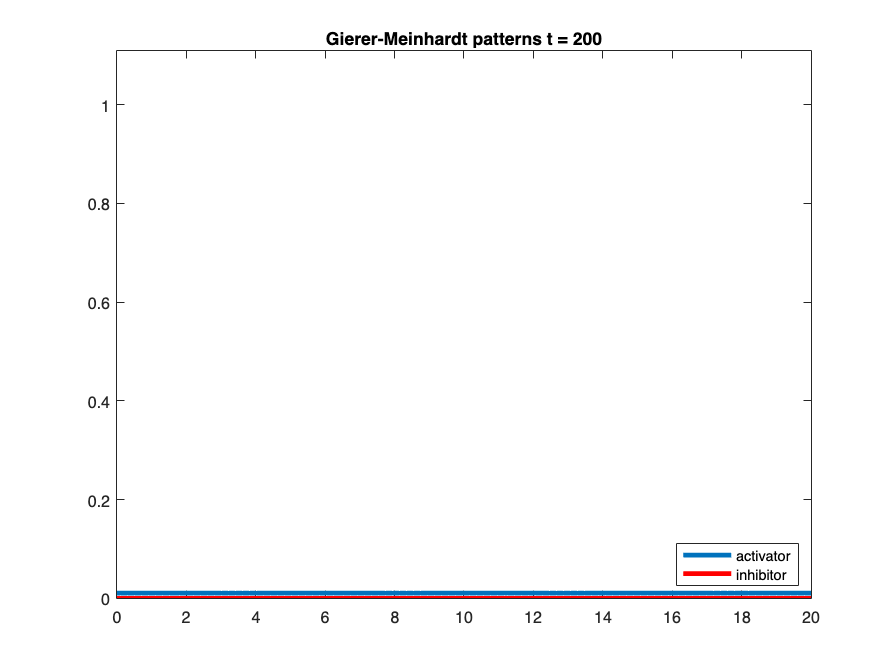

    0.0500
    1.0500
    0.0100



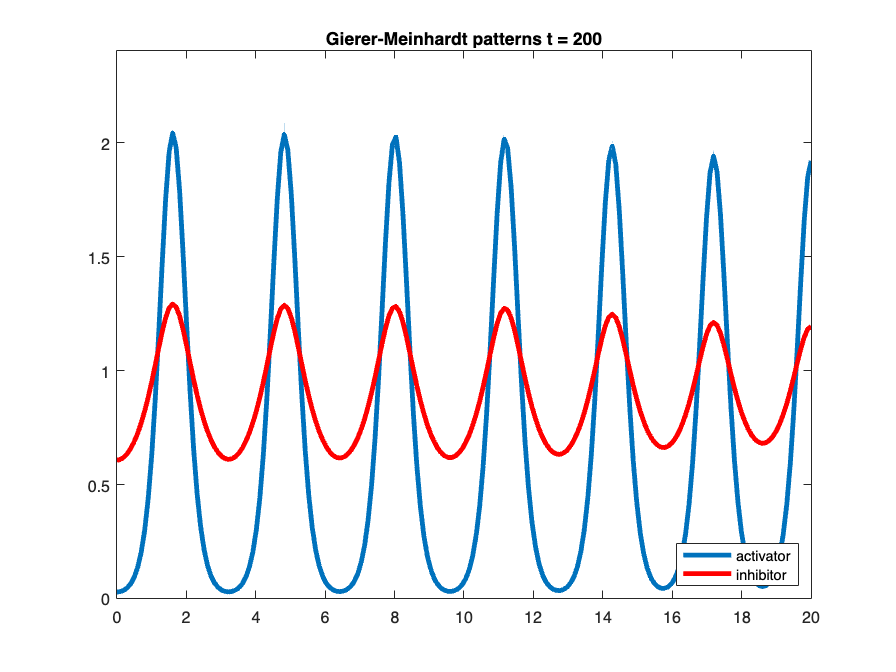

    0.0500
    1.5500
    0.0100



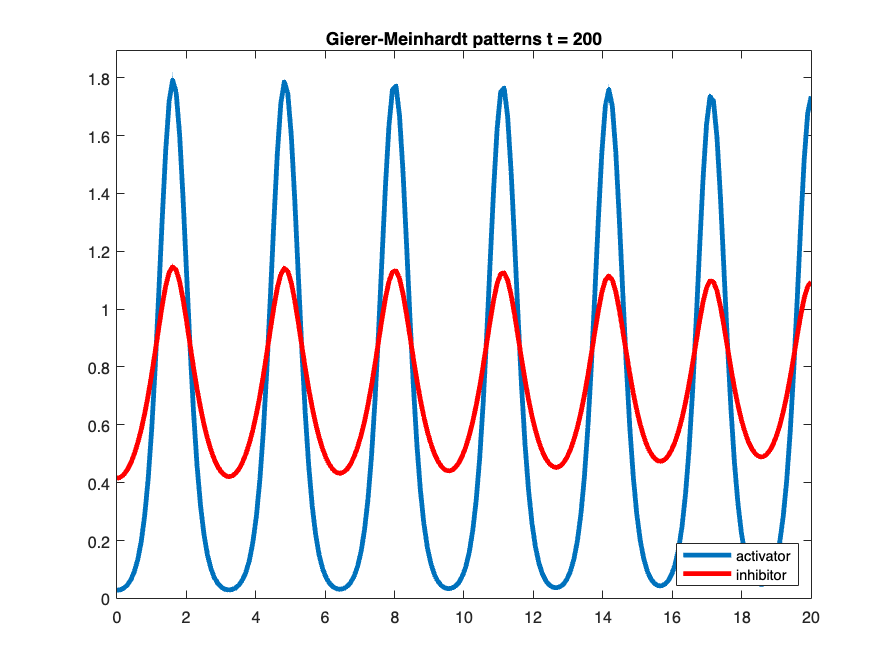

    0.0500
    2.0500
    0.0100



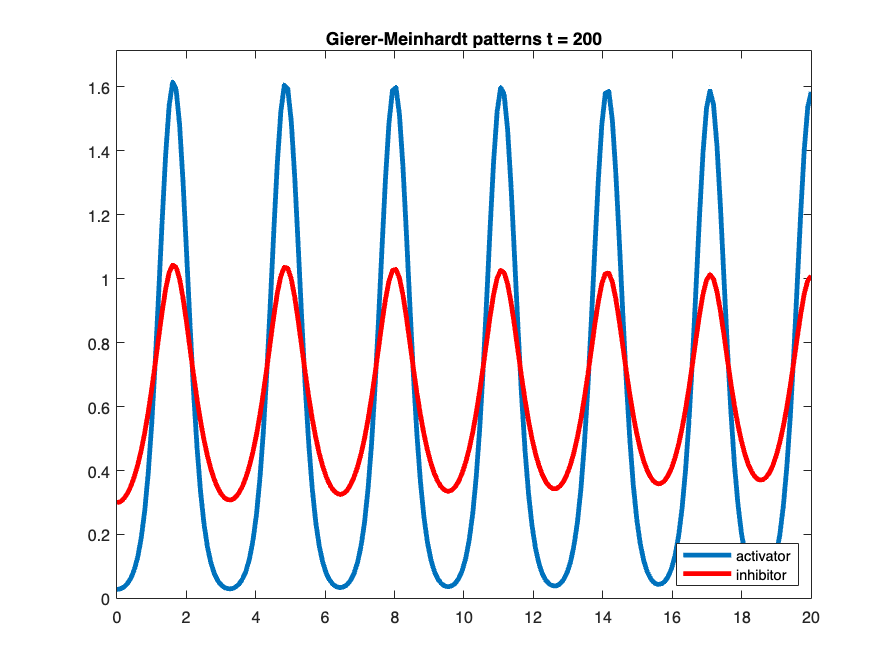

    0.0500
    2.5500
    0.0100



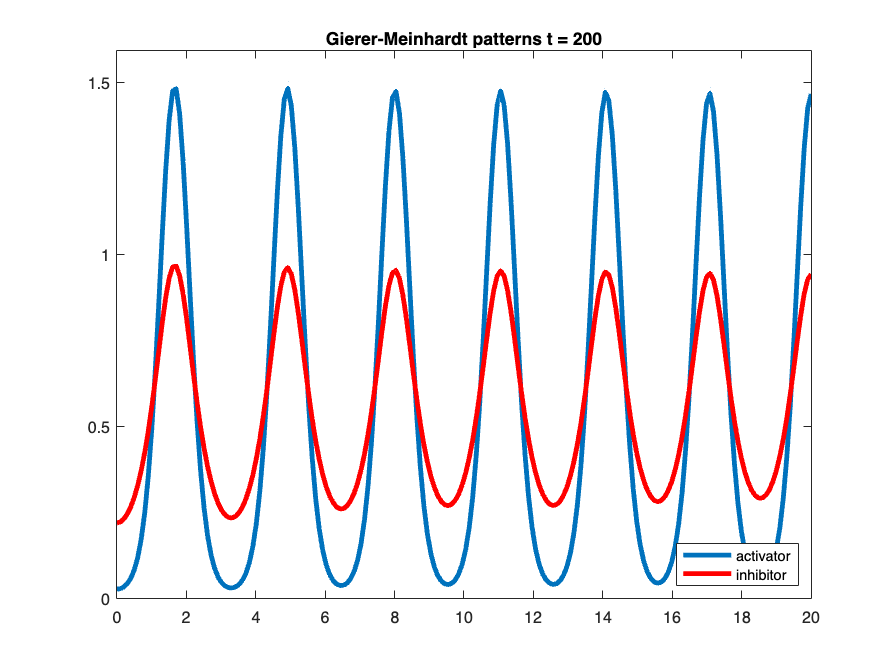

    0.0500
    3.0500
    0.0100



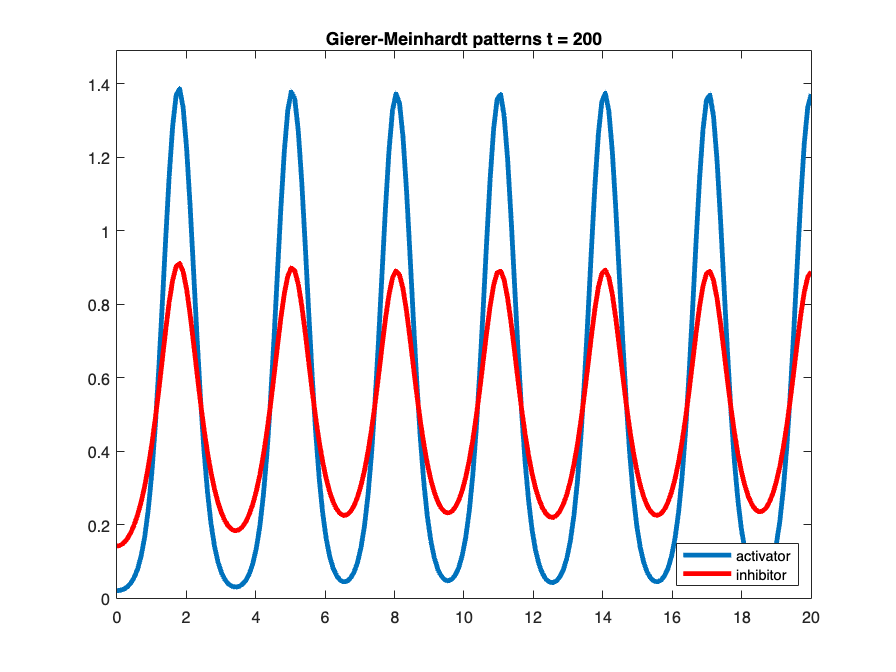

    0.0500
    3.5500
    0.0100



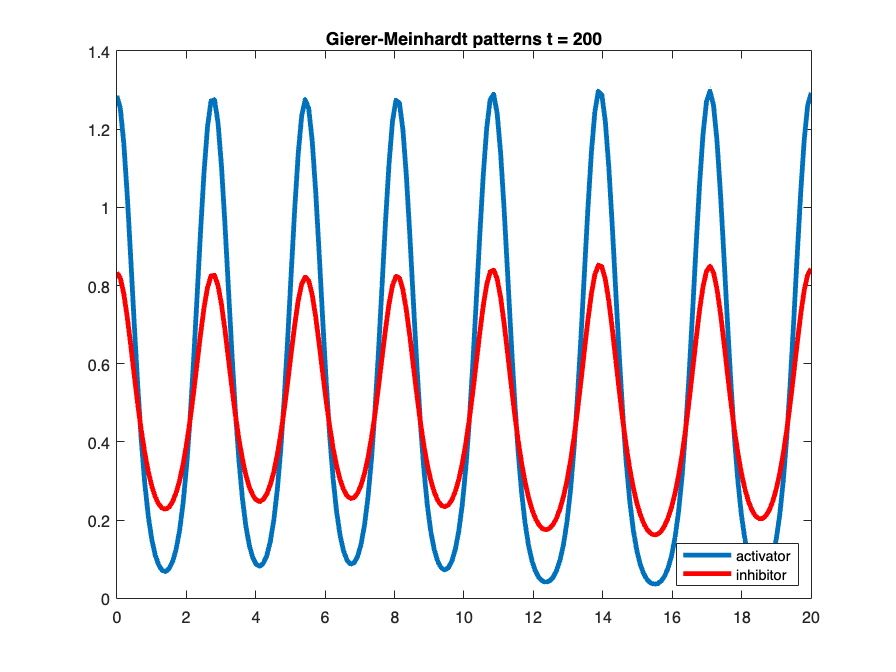

    0.0500
    4.0500
    0.0100



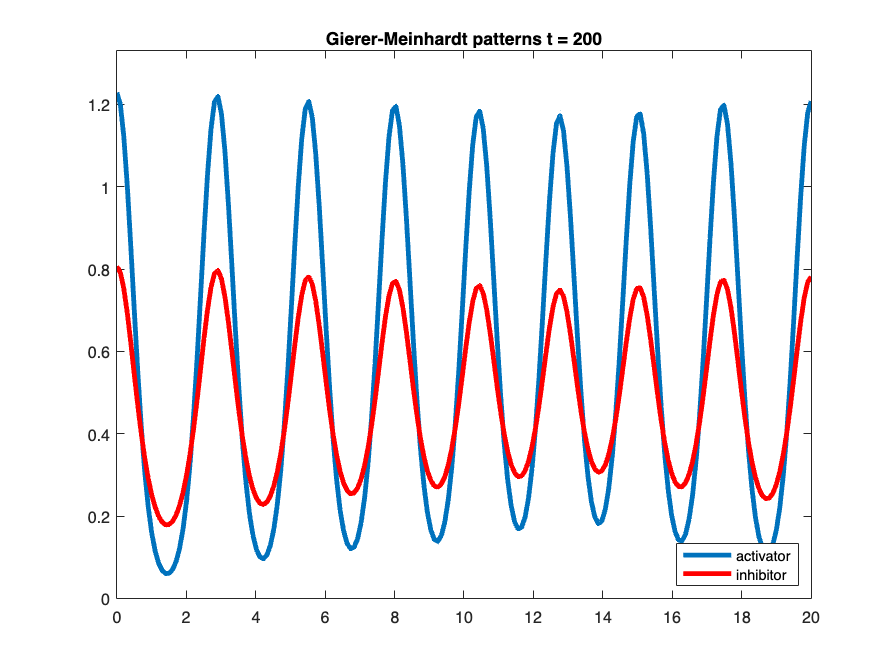

    0.0500
    4.5500
    0.0100



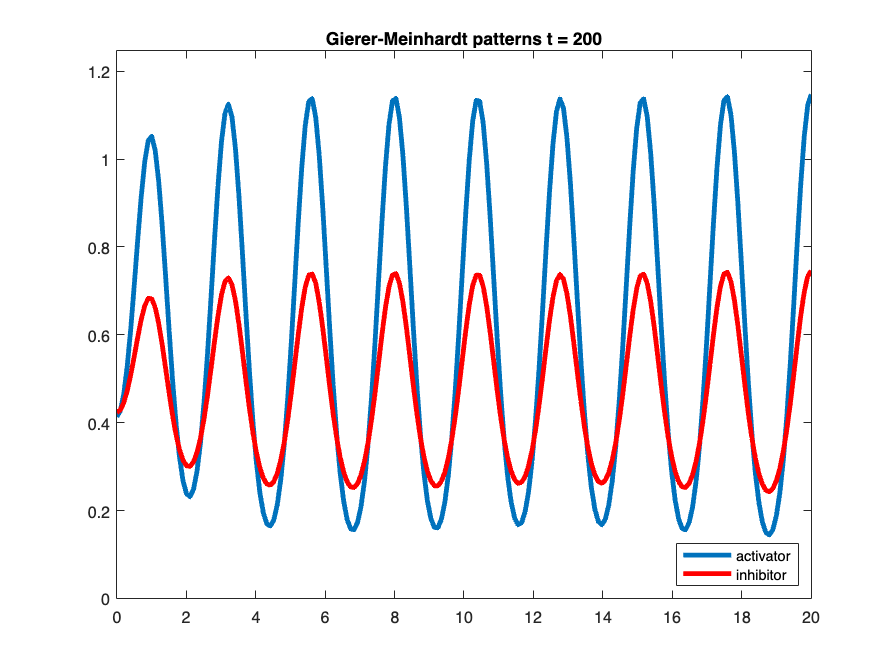

    0.1500
    0.0500
    0.0100



    0.1500
    0.5500
    0.0100



    0.1500
    1.0500
    0.0100



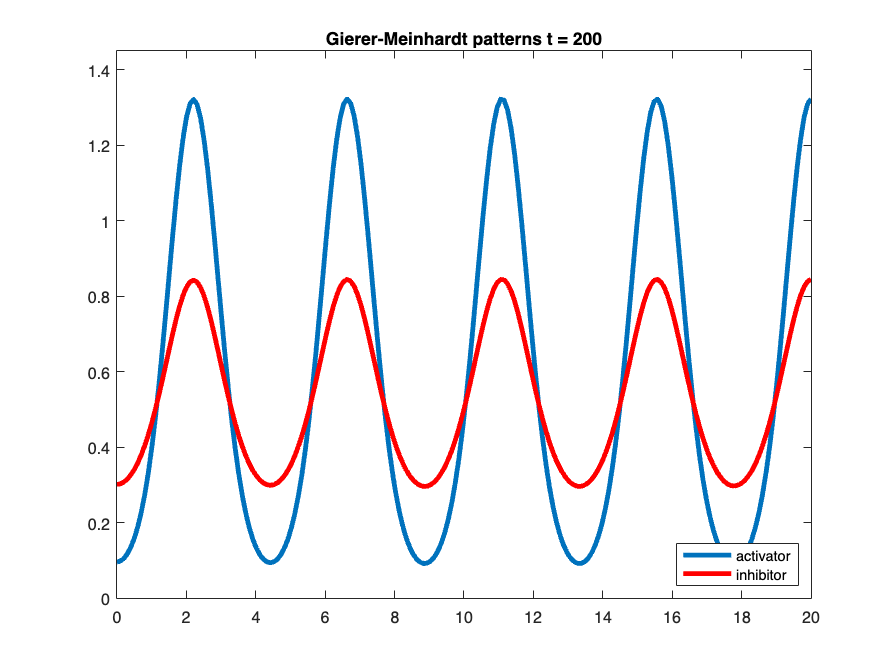

    0.1500
    1.5500
    0.0100



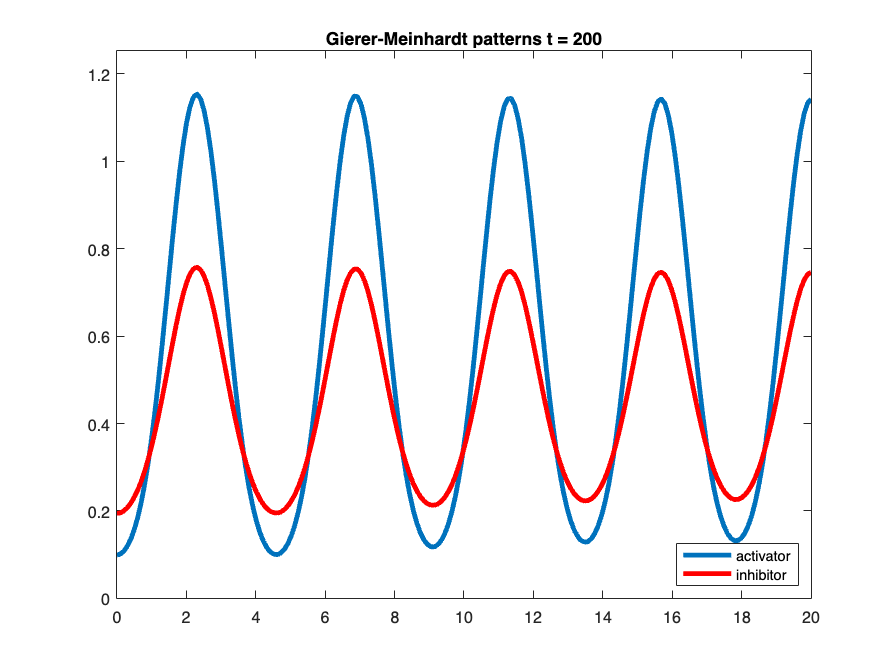

    0.1500
    2.0500
    0.0100



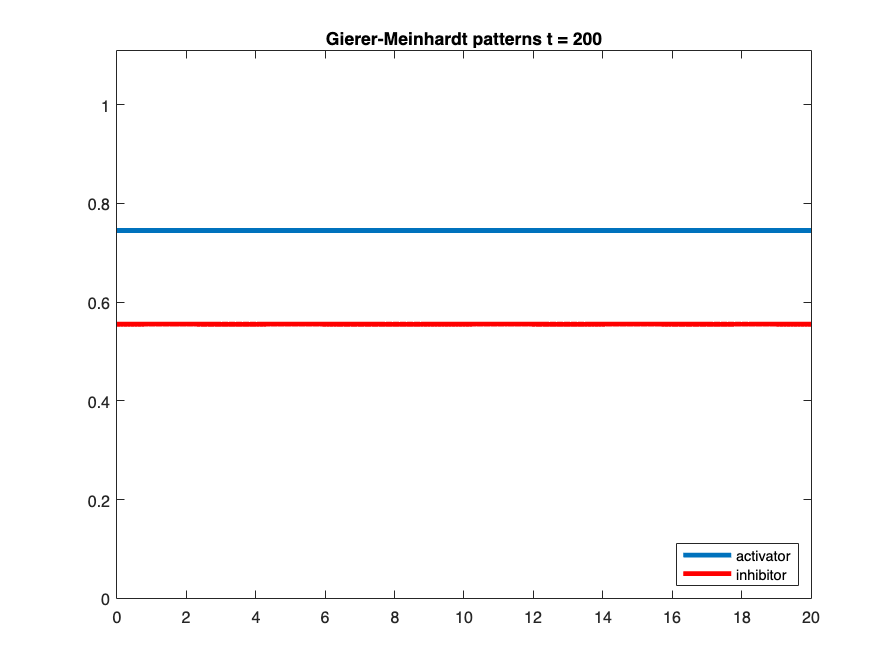

    0.1500
    2.5500
    0.0100



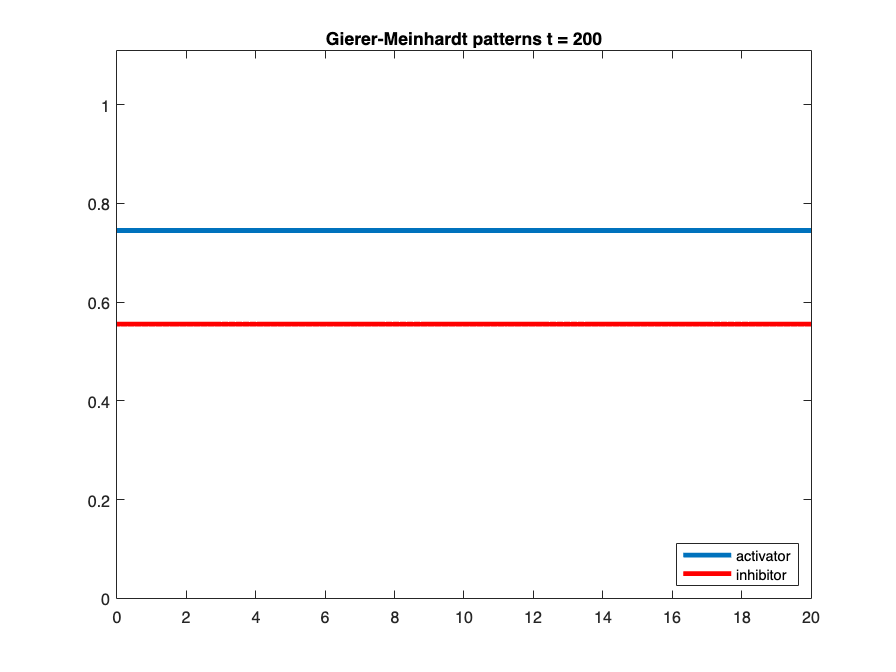

    0.1500
    3.0500
    0.0100



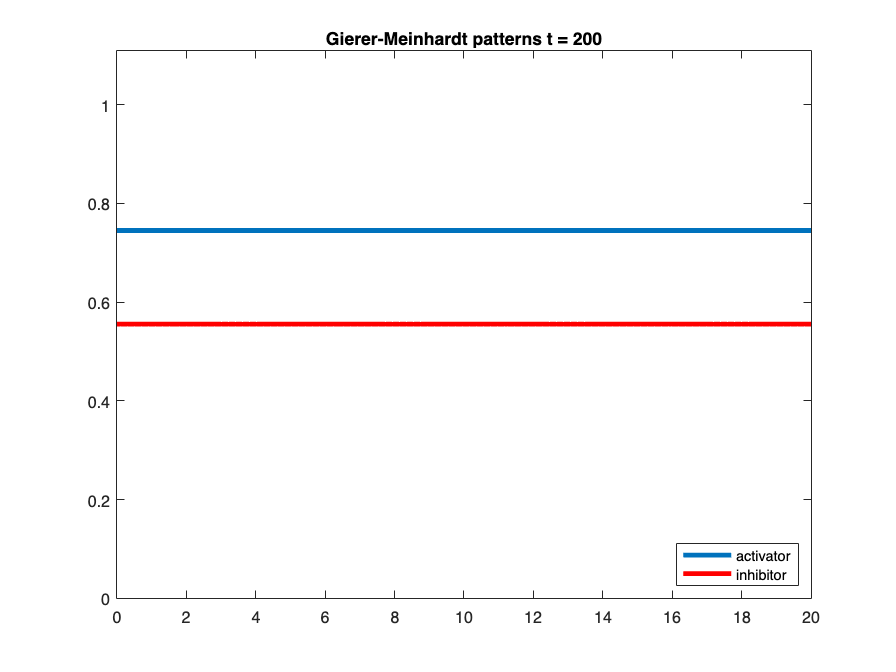

    0.1500
    3.5500
    0.0100



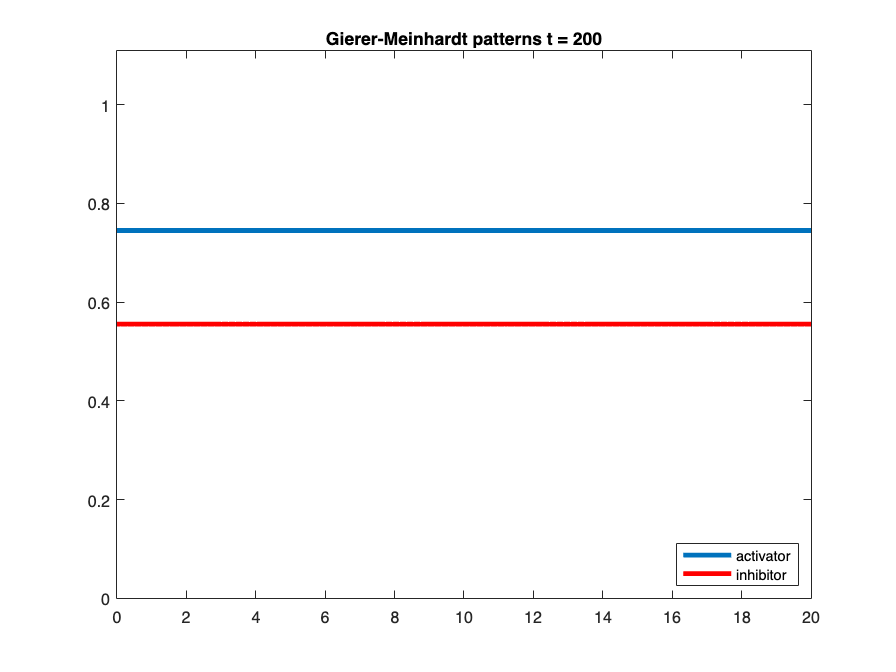

    0.1500
    4.0500
    0.0100



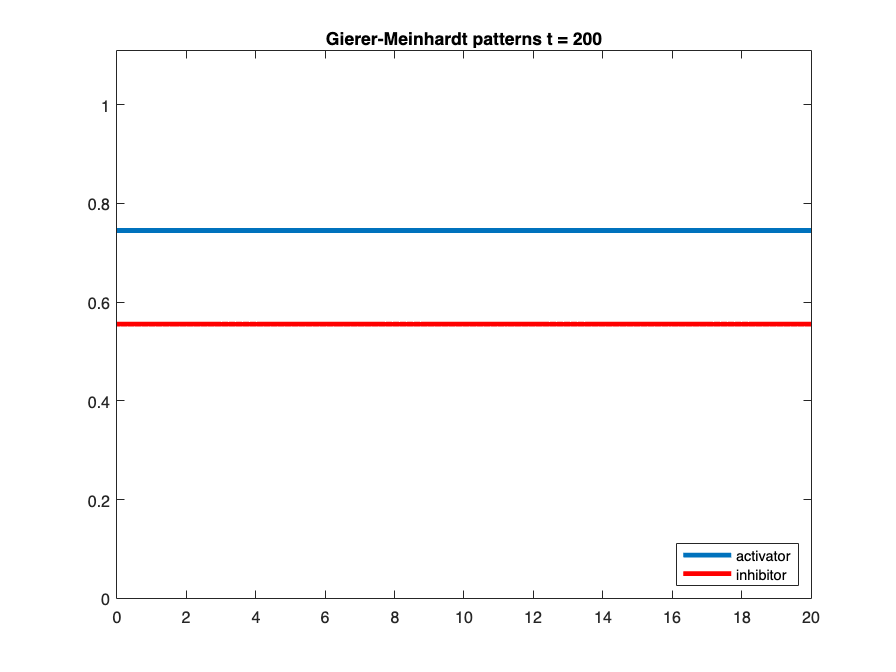

    0.1500
    4.5500
    0.0100



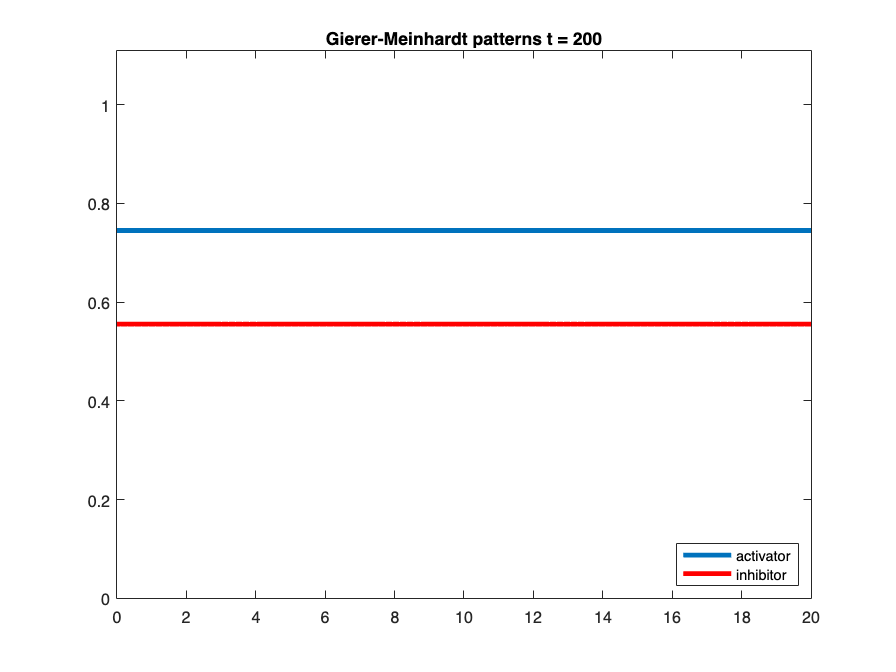

    0.2500
    0.0500
    0.0100



    0.2500
    0.5500
    0.0100



    0.2500
    1.0500
    0.0100



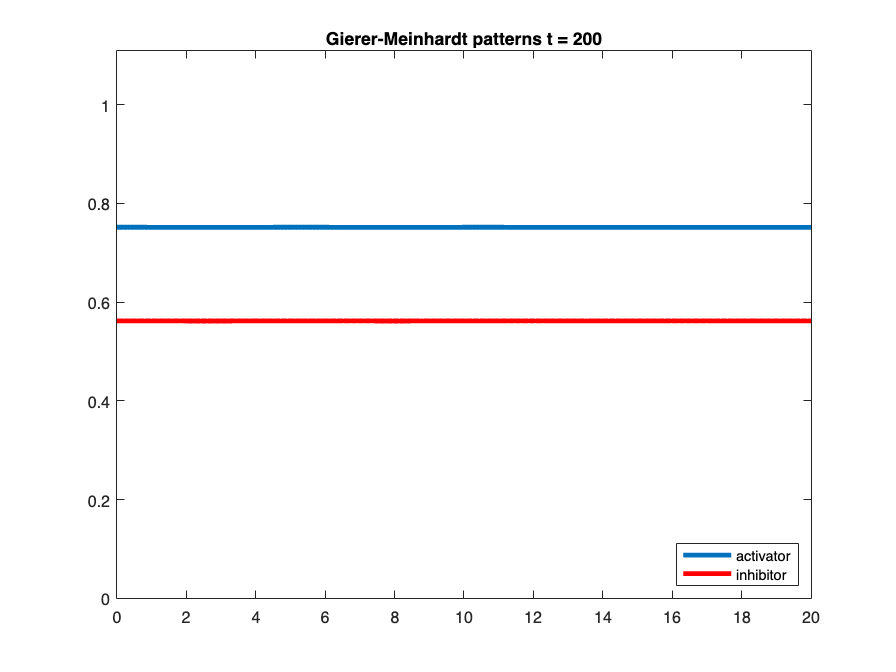

    0.2500
    1.5500
    0.0100



    0.2500
    2.0500
    0.0100



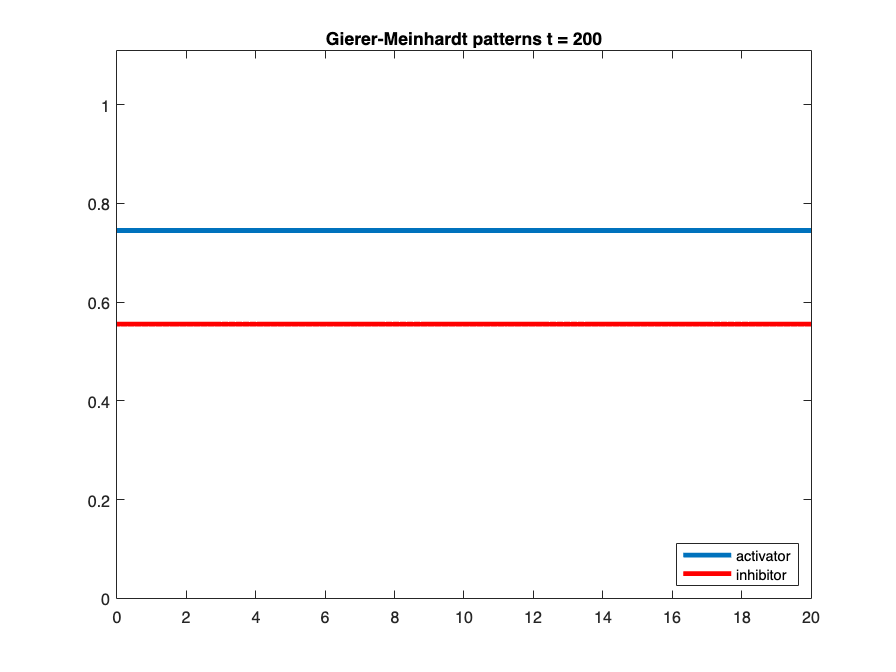

    0.2500
    2.5500
    0.0100



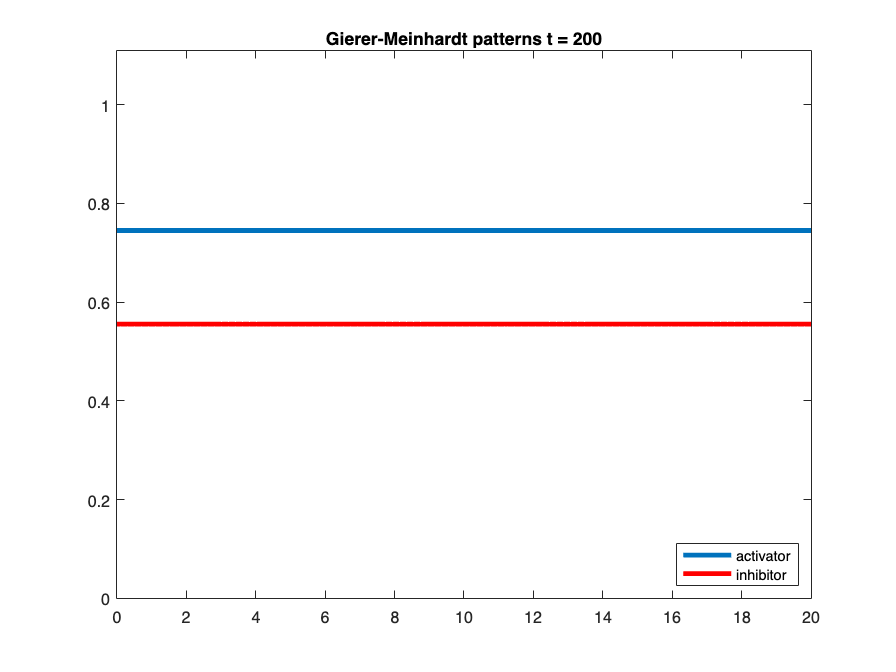

    0.2500
    3.0500
    0.0100



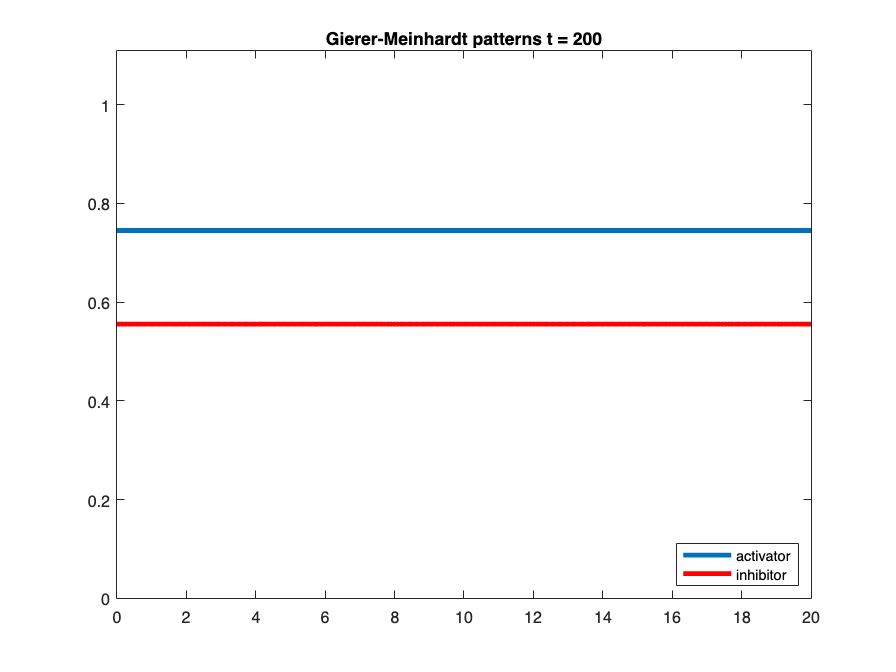

    0.2500
    3.5500
    0.0100



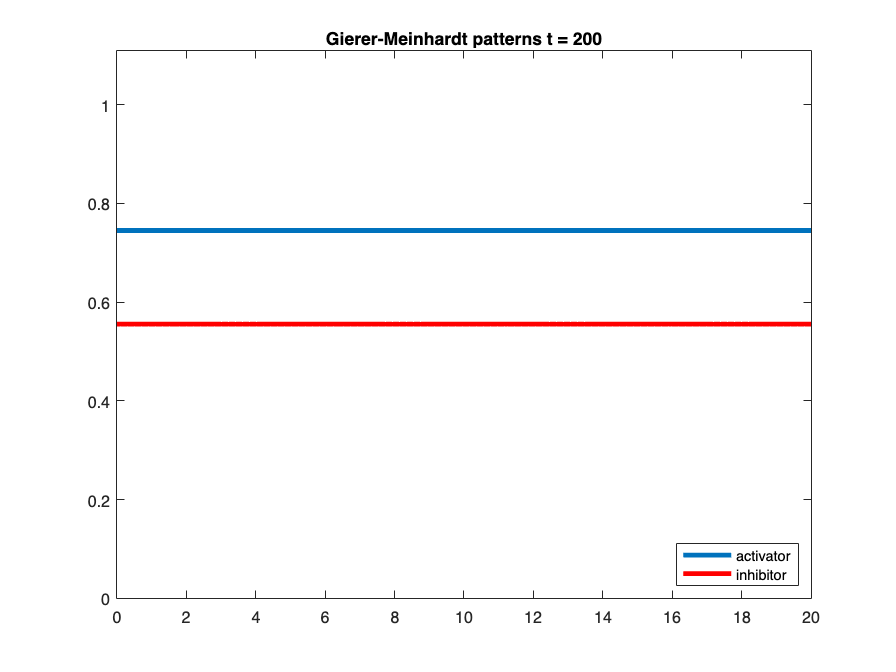

    0.2500
    4.0500
    0.0100



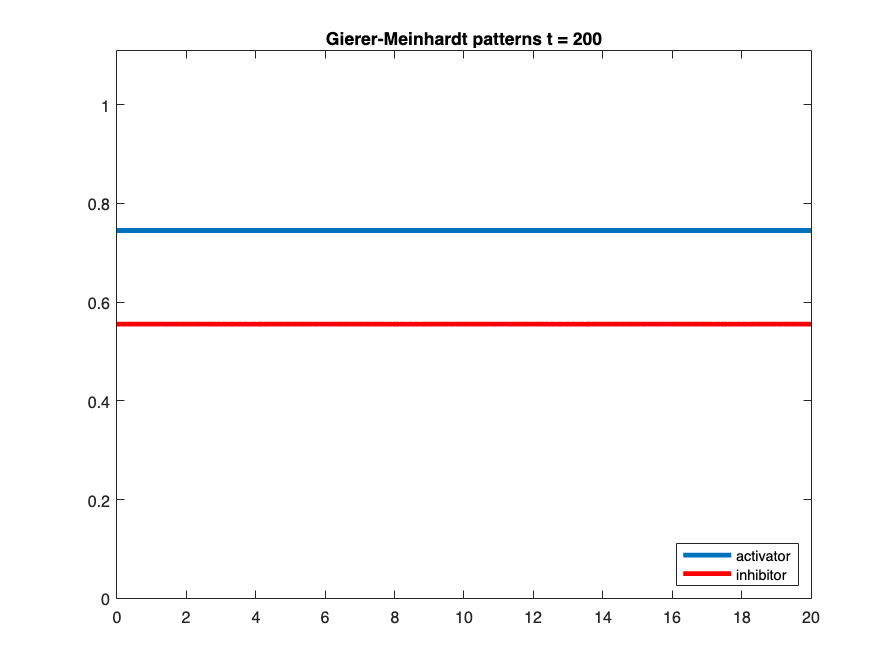

    0.2500
    4.5500
    0.0100



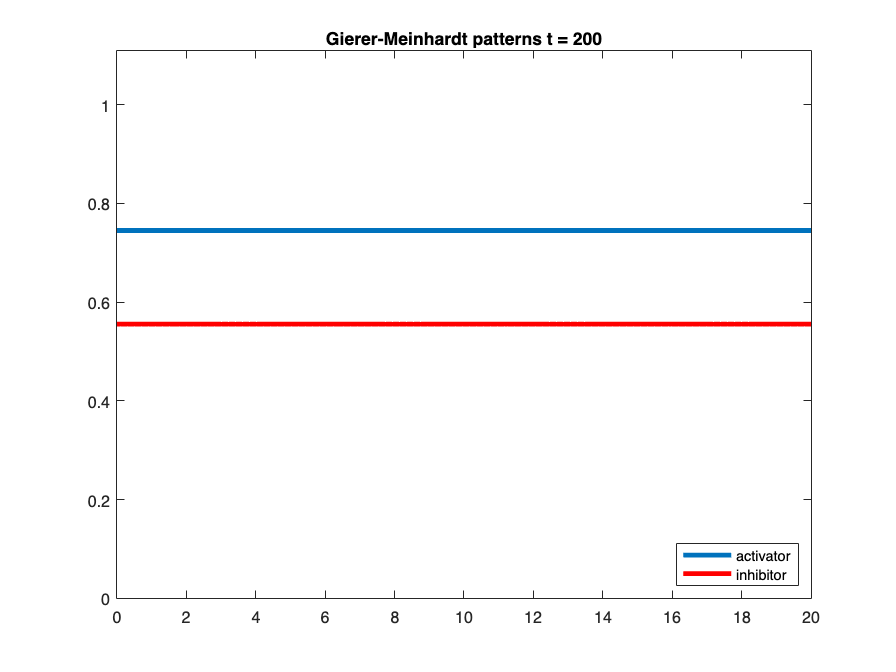

    0.3500
    0.0500
    0.0100



    0.3500
    0.5500
    0.0100



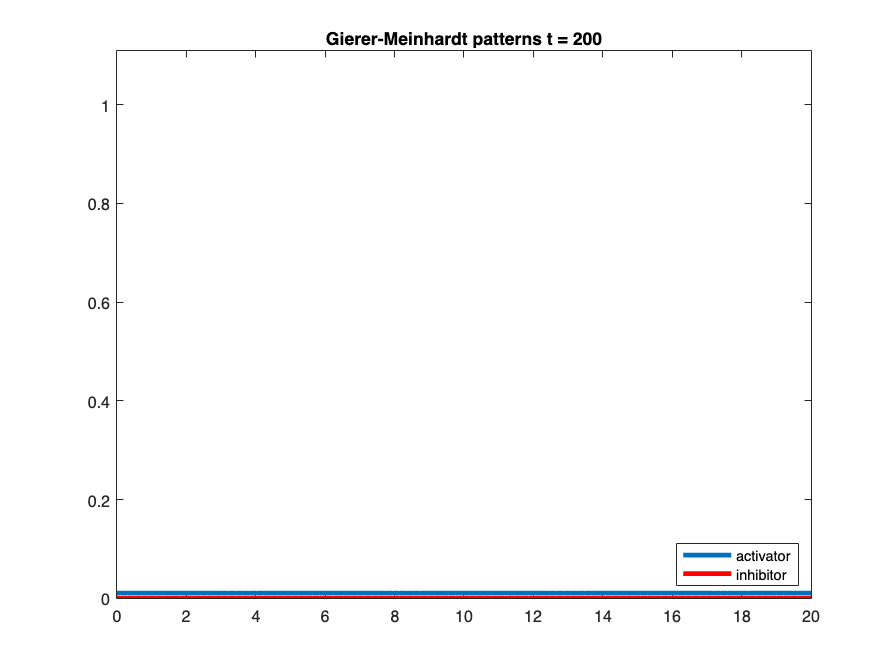

    0.3500
    1.0500
    0.0100



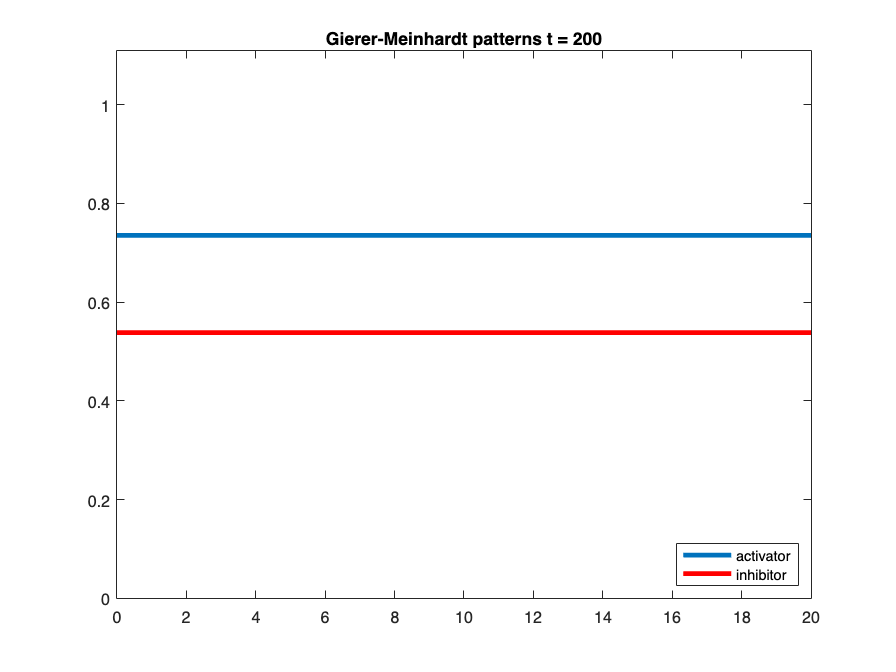

    0.3500
    1.5500
    0.0100



    0.3500
    2.0500
    0.0100



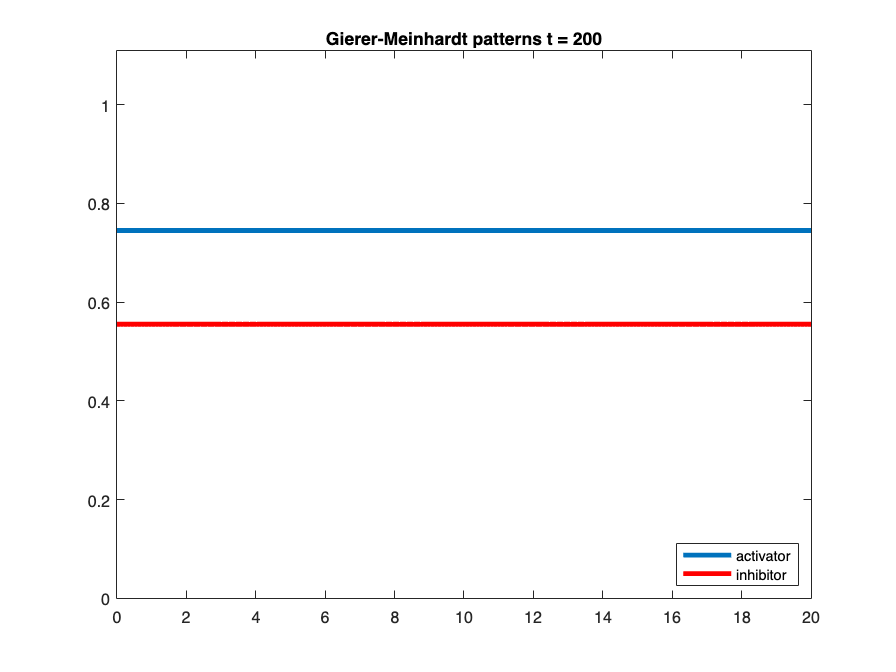

    0.3500
    2.5500
    0.0100



    0.3500
    3.0500
    0.0100



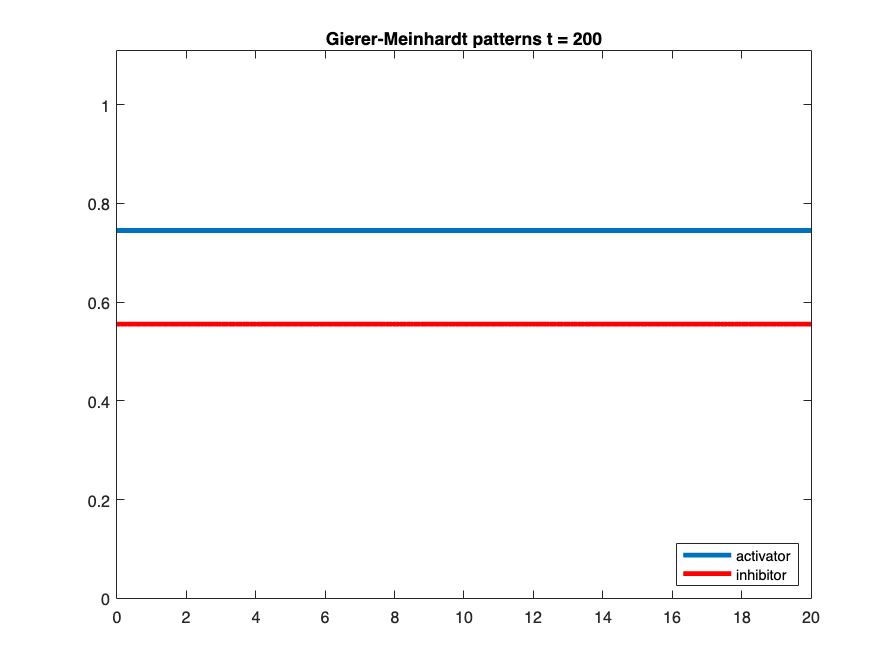

    0.3500
    3.5500
    0.0100



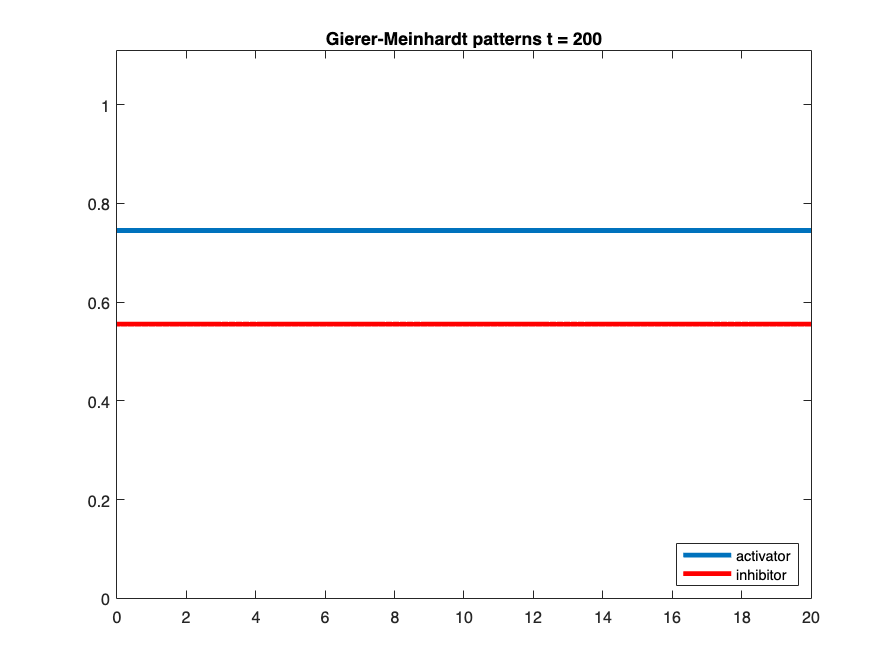

    0.3500
    4.0500
    0.0100



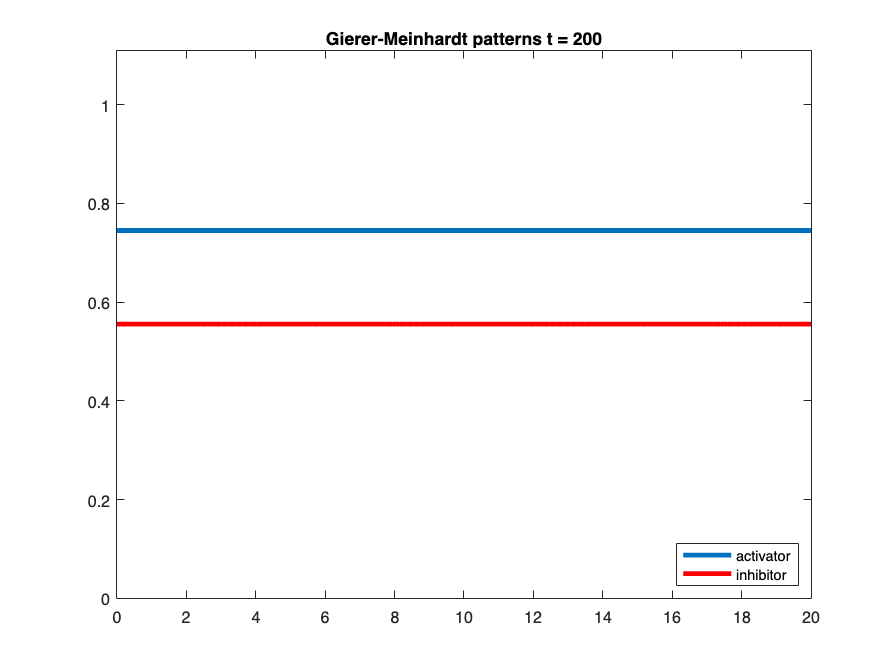

    0.3500
    4.5500
    0.0100



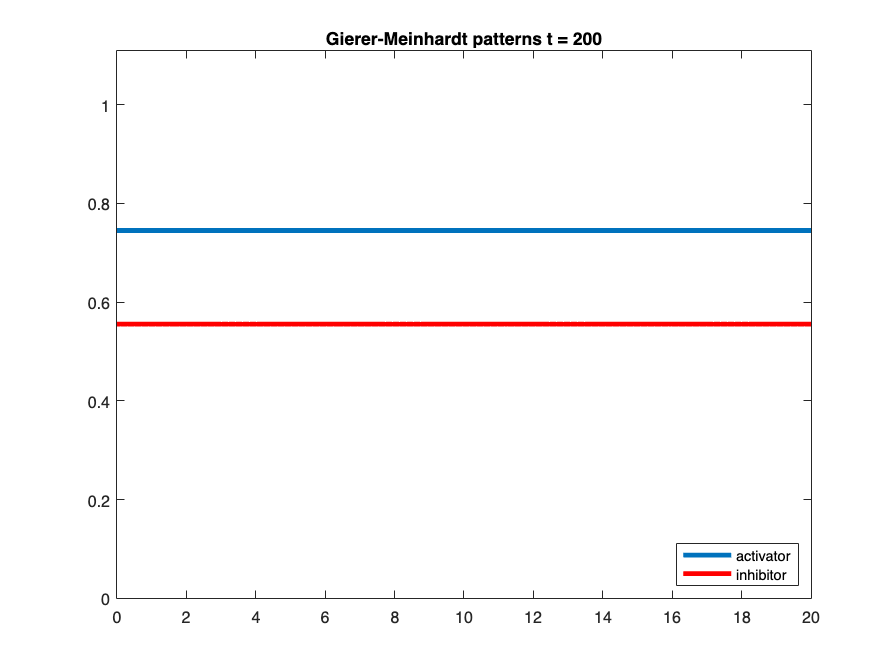

    0.4500
    0.0500
    0.0100



    0.4500
    0.5500
    0.0100



    0.4500
    1.0500
    0.0100



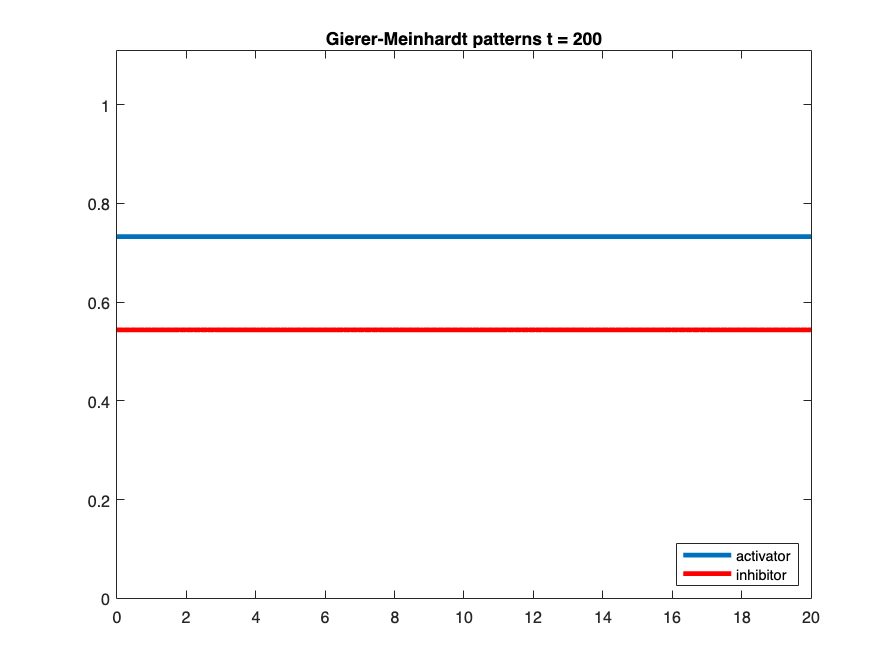

    0.4500
    1.5500
    0.0100



    0.4500
    2.0500
    0.0100



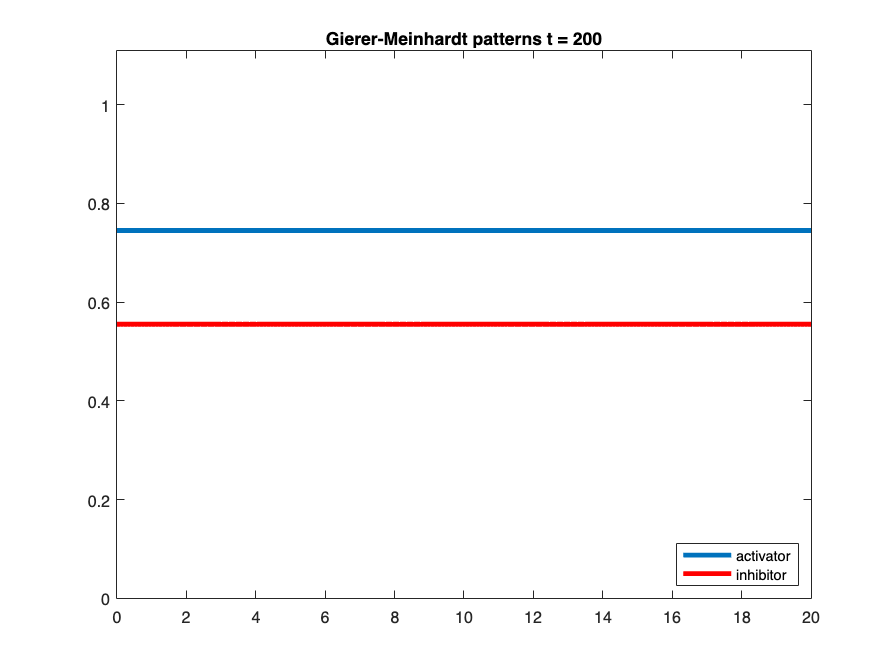

    0.4500
    2.5500
    0.0100



    0.4500
    3.0500
    0.0100



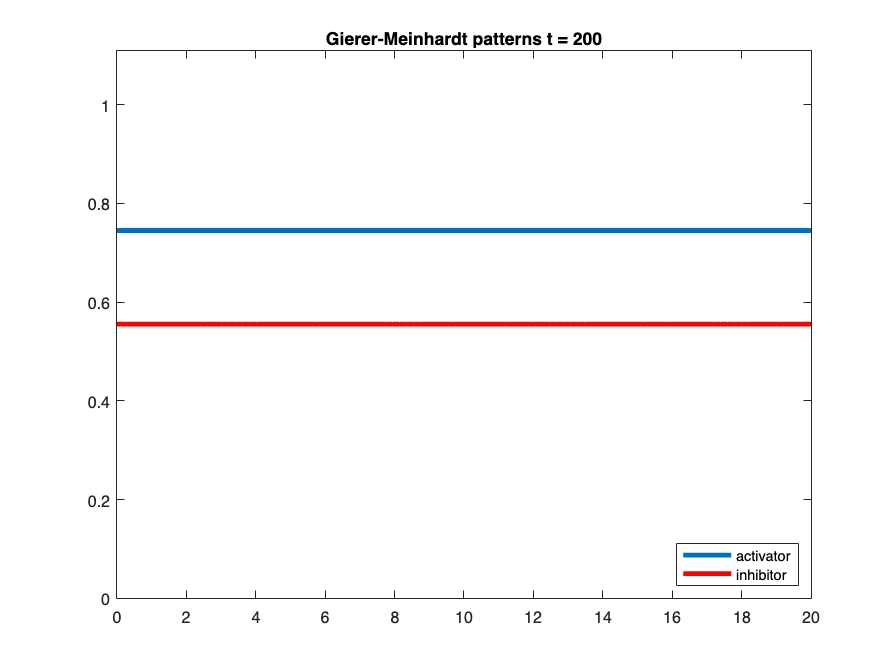

    0.4500
    3.5500
    0.0100



    0.4500
    4.0500
    0.0100



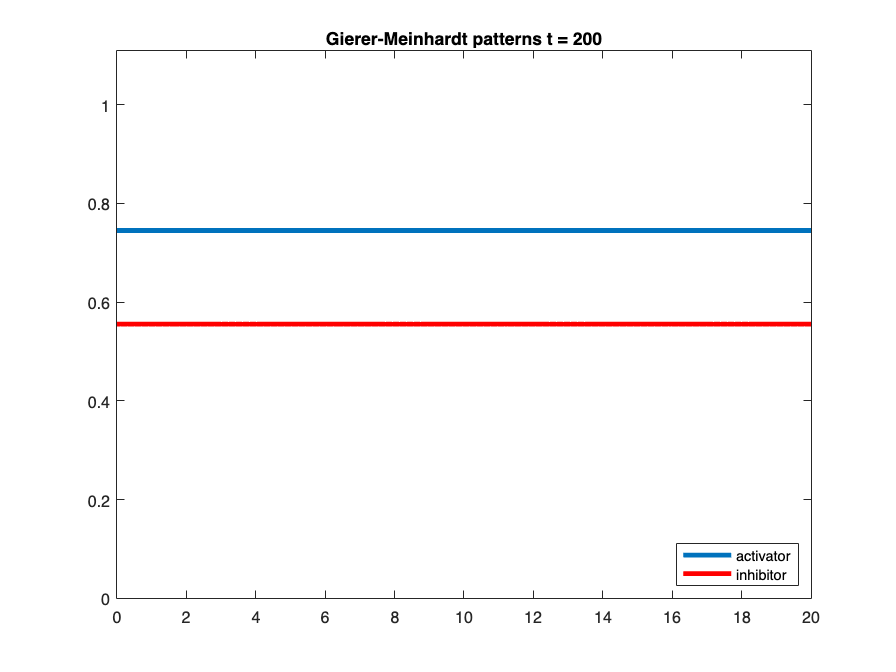

    0.4500
    4.5500
    0.0100



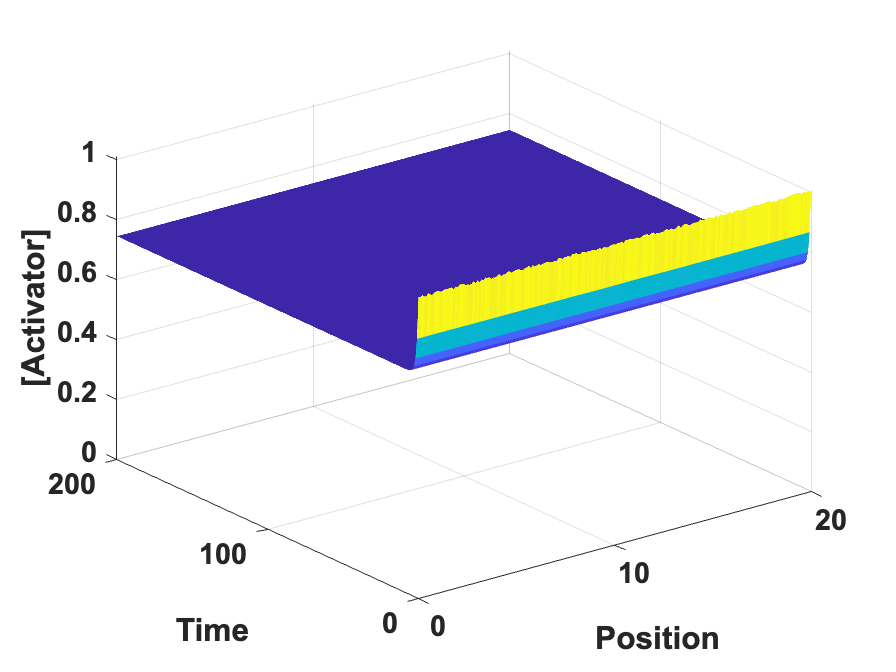

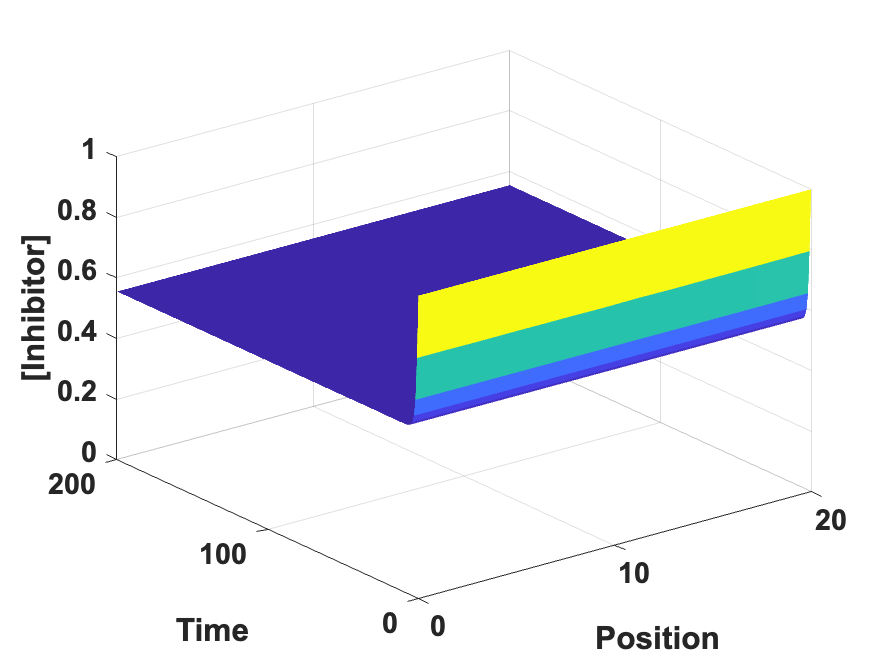

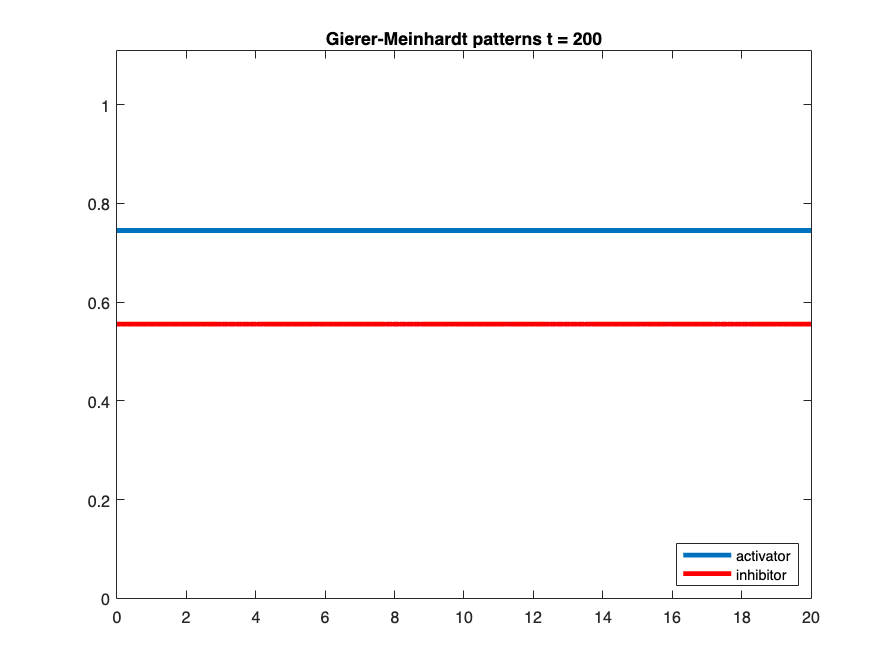

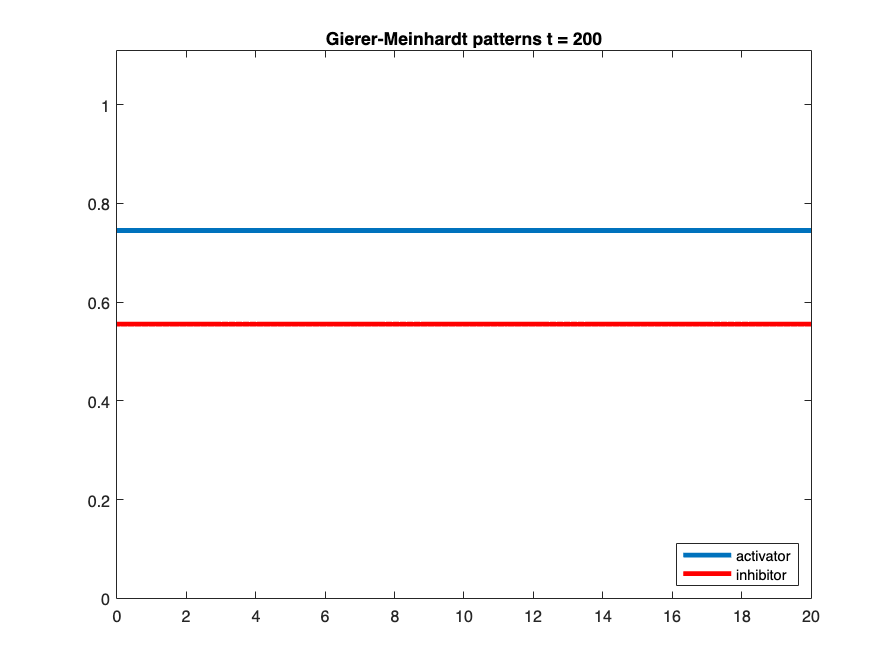

tmax = 200;
ctr = 1;
for x1 = 0.05:0.1:0.5
    for x2 = 0.05:0.5:5
        P = [x1; x2; 0.01];     %trivial solution
        disp(P);
        sol = GM_solve_record_JH(P, tmax, delt, L, 'test_pattern2.avi');
        
        t = linspace(0,tmax,tmax/delt);
        x = linspace(0,L,200); %the mesh on which we solve (200 space points)
        figure(100+ctr);
        for n = 2:2:length(t)
            set(gca, 'FontSize', 18, 'LineWidth', 1); %<- Set properties
            plot( x , sol(n,:,1), 'LineWidth',3);
            hold on
            plot( x , sol(n,:,2), 'r', 'LineWidth',3);
            hold off
            legend('activator', 'inhibitor', 'Location', 'SouthEast');
            title(strcat('Gierer-Meinhardt patterns t =' , sprintf(' %d ', ceil(t(n)))));
            axis([0 L 0 max(max(max(sol(:,:,:))))+0.1])
        end
        ctr = ctr + 1;
    end
end

### Question 5.

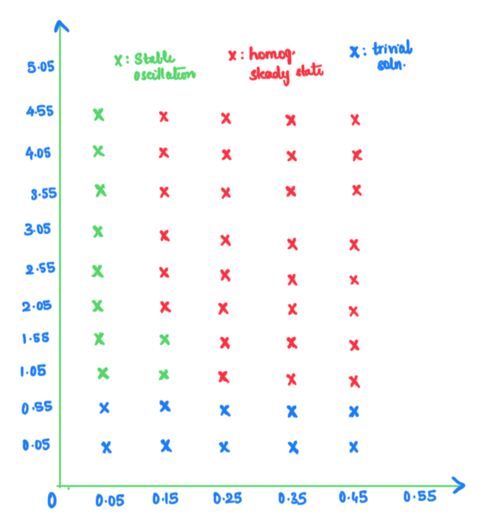

### Question 6.